clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = 273.15+20;
param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]


param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


simtime = 10*60;
 
% param.model.Dg
% inv(param.ctrl.Lambda_Bar)
% param.model.Dg*param.ctrl.Lambda_Bar
% Skriver en diagonal -1 på integralstaten.
% for i=1:4
%     param.model.A(3*i,3*i) = -1;
% end

% s = tf('s');
% % Wdelta = eye(4)*tf([0,0.1],[1,0.1]);
% % Wdelta = eye(4)*1/(1/0.1*s+1);
% Wdelta = 0.9*eye(4)*tf(1,1);
% WdeltaSS = ss(Wdelta);
% if isempty(WdeltaSS.A)
%     param.model.Awd = zeros(4);
%     param.model.Bwd = zeros(4);
%     param.model.Cwd = zeros(4);
% else
%     param.model.Awd = WdeltaSS.A;
%     param.model.Bwd = WdeltaSS.B;
%     param.model.Cwd = WdeltaSS.C;
% end
% param.model.Dwd = WdeltaSS.D;
% param.model.Dwd = eye(4);


## Control

% [param.ctrl.Ks] = control.DesignProcedure1(param,0); 
param = control.DesignProcedure2(param,0,0);

Evaluation of design procedure 2 
Q is positive definite


ans =     0.0014    0.0014    0.0014    0.0082    0.1780    0.1794    0.1794    0.1820    3.0391    4.1899    4.2894    4.3188


Gamma is found to be:


ans = 1.0203

Eigenvalues of the decoupled systems are all negative 


ans =    -5.8861   -3.7193   -0.0473  -35.3607   -4.0279   -0.0231  -39.0341   -3.9902   -0.0230  -31.9229   -3.9896   -0.0225


Eigenvalues of the coupled systems are all negative 


ans =   -90.8194  -80.2837  -62.6284  -12.0194   -3.8636   -4.0289   -3.9907   -3.9912   -0.0473   -0.0225   -0.0231   -0.0230


% param.ctrl.Ks = control.DesignProcedureWeight(param,0,0);
% param.ctrl.Ks = control.DesignProcedureRealUncertainties(param,1,{[-0.1,0.1],[-0.1,0.1],[-0.1,.1],[-0.1,.1]});
% param.ctrl.Ks = control.DesignProcedureRealUncertainties(param,1,{[-1,1]});


K = blkdiag(param.ctrl.Ks(:,:,1),param.ctrl.Ks(:,:,2),param.ctrl.Ks(:,:,3),param.ctrl.Ks(:,:,4));

% Bw = -blkdiag([0;1;0],[0;1;0],[0;1;0],[0;1;0]);
Bw = -blkdiag([0;0;1],[0;0;1],[0;0;1],[0;0;1]);
% Cz = blkdiag([0 1 0],[0 1 0],[0 1 0],[0 1 0]);
% Cz = blkdiag([0 0 1],[0 0 1],[0 0 1],[0 0 1]);
Cz = blkdiag([1 0 0],[1 0 0],[1 0 0],[1 0 0]);
Cy = eye(12);

% Am = [param.model.A+param.model.B*K*Cy, zeros(12,4);
%       WdeltaSS.B*K*Cy, WdeltaSS.A];
% 
% Bm = [param.model.B;
%       zeros(4,4)]; 
% 
% Cm = [WdeltaSS.D*K*Cy, WdeltaSS.C];
% 
% Dm = [zeros(4,4)];
s=tf('s');
NN = Cz/(s*eye(12)-(param.model.A+param.model.B*K))*Bw;
% 
% s = tf('s');
% M = K * eye(12)/(s * eye(12) - (param.model.A + param.model.B * K * eye(12)) )*param.model.B;
hinfnorm(NN)

ans = 1.3333

## Structured uncertainties

s = tf('s');

w = 1;
M = K*eye(12)/(s*eye(12) - ( param.model.A + param.model.B*K*eye(12) ) )*param.model.B;
hinfnorm(M)

ans = 1.2126

max(max(sigma(M)))

ans = 1.2108

W = logspace(-1,3,400);
SV = sigma(M, W)

SV =     1.0188    1.0197    1.0206    1.0215    1.0225    1.0235    1.0246    1.0257    1.0268    1.0280    1.0293    1.0306    1.0319    1.0333    1.0348    1.0363    1.0379    1.0396    1.0413    1.0431    1.0449    1.0469    1.0489    1.0509    1.0531    1.0553    1.0576    1.0600    1.0625    1.0651    1.0677    1.0705    1.0733    1.0762    1.0792    1.0823    1.0855    1.0888    1.0921    1.0956    1.0991    1.1027    1.1064    1.1102    1.1141    1.1180    1.1220    1.1260    1.1301    1.1343
    1.0141    1.0147    1.0154    1.0161    1.0168    1.0176    1.0184    1.0192    1.0200    1.0209    1.0219    1.0228    1.0238    1.0249    1.0259    1.0271    1.0283    1.0295    1.0307    1.0321    1.0334    1.0348    1.0363    1.0378    1.0394    1.0410    1.0427    1.0445    1.0463    1.0482    1.0501    1.0521    1.0542    1.0563    1.0585    1.0607    1.0630    1.0654    1.0679    1.0704    1.0729    1.0756    1.0783    1.0810    1.0838    1.0867    1.0896    1.0925    1.0955    

spectral = zeros(1,length(W));
Ms = freqresp(M,W);
for i=1:length(W)   
    spectral(i) = abs(eigs(Ms(:,:,i),1));
end

[bounds,muinfo]  = mussv(frd(M,W),[4,0],'an');

Points completed: 400/400


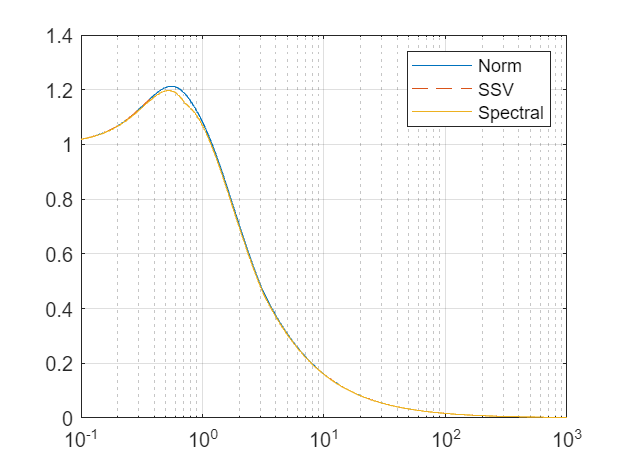


[VDelta,VSigma,VLmi] = mussvextract(muinfo);
VDelta.responsedata(:,:,:);
upperBound = bounds(1).ResponseData(:);

figure()
semilogx(W,max(SV),W,upperBound,'--',W,spectral)
% ylim([0;4])
legend('Norm', 'SSV', 'Spectral')
grid on

set(gcf, 'PaperUnits', 'centimeters');
set(gcf, 'PaperPosition', [0 0 16 9]);
% saveas(gcf,'../Images/SSV_PLOT_Procedure2','epsc')

% H = [An, B*B'; -(K*eye(12))'*(K*eye(12)), -An']

% W = logspace(-1,3,100);
% Ms = freqresp(Mn2,W);
% yalmip('clear')
% gamma = 0.01;
% % D = sdpvar(4,4,'symmetric','complex');
% % Q = D*D'
% D = sdpvar(4,4,'toeplitz','complex');
% Q = D-diag(imag(diag(D)))*sqrt(-1)
% constraints = [Ms(40)*Q*Ms(40)' <= gamma^2*Q, Q>=0]
% options = sdpsettings('verbose',0,'solver','mosek');
% sol = optimize(constraints,[],options)
% value(Q)
% eig(value(Q))

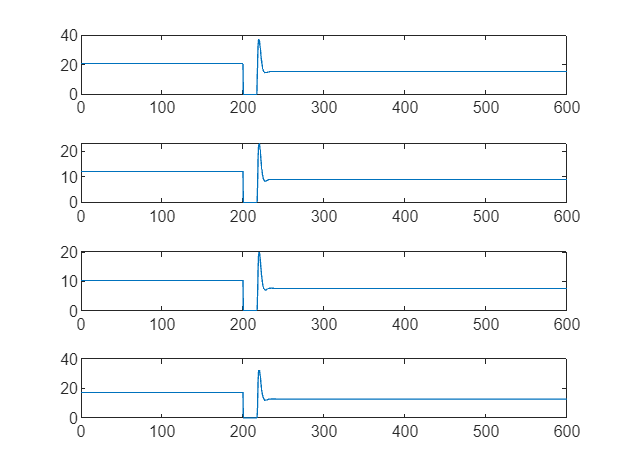

figure()
tiledlayout('vertical')
for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    [t,x] = ode23s(@(t,x)model.decoupledDynamics(t,x,i,param,200),[0 simtime],x0);
    decoupledResults(i).time = t;
    decoupledResults(i).Tw = x(:,1);
    decoupledResults(i).Ta = x(:,2);
    decoupledResults(i).T = x(:,3);

    q = zeros(1,length(t));
      for k=1:length(t)
        [~,q(k)] = model.decoupledDynamics(t(k),x(k,:)',i,param);
      end
      nexttile
      plot(t,q*3600)
end

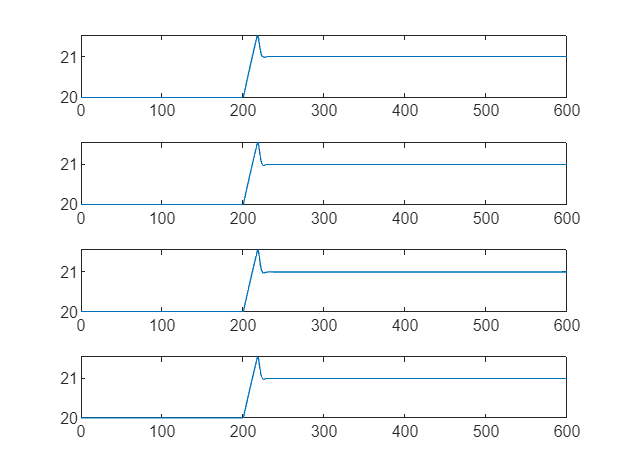



figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15)
end

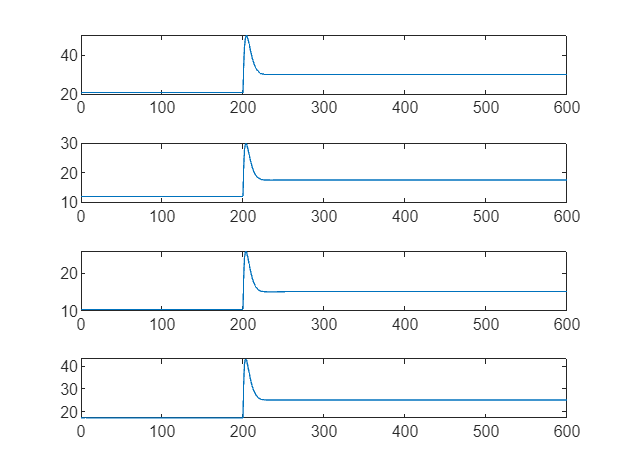


x0 = [param.ctrl.T_wOP.'; param.ctrl.T_aOP.'; zeros(4,1)];
% options = odeset('RelTol',1e-8,'AbsTol',1e-10);
[t,x] = ode23s(@(t,x)model.coupledDynamics(t,x,param,200),[0 simtime],x0);
coupledResults.time = t;
coupledResults.Tw = x(:,1:4);
coupledResults.Ta = x(:,5:8);
coupledResults.T = x(:,9:12);

q = zeros(4,length(x(:,1)));
for k=1:length(x(:,1))
  [~,q(:,k)] = model.coupledDynamics(t(k),x(k,:)',param);
end
figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(t,q(i,:)*3600);
end

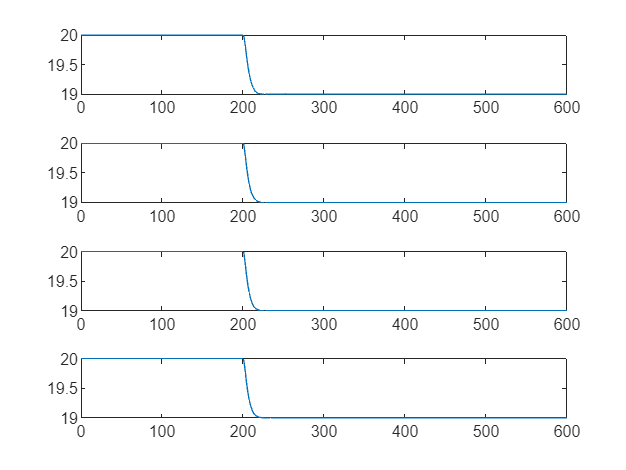



figure()
tiledlayout('vertical')

for i=1:4
    nexttile
    plot(coupledResults.time,coupledResults.Ta(:,i)-273.15)
end

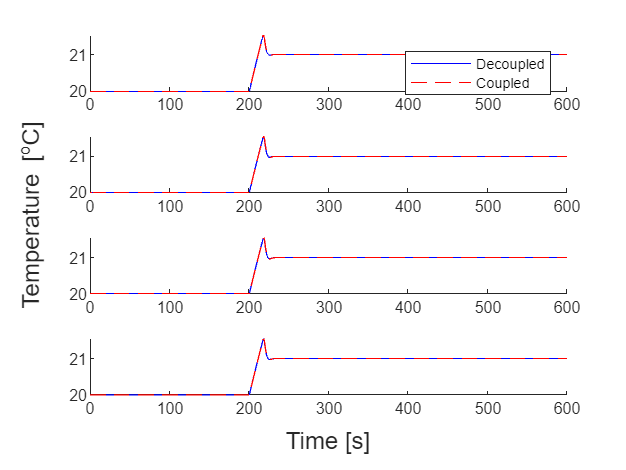

figure()
f = tiledlayout('vertical');
for i=1:4
    nexttile
    hold on
    plot(decoupledResults(i).time,decoupledResults(i).Ta-273.15,'blue')
    plot(coupledResults.time,coupledResults.Ta(:,i)-273.15,['red','--'])
    if i==1
        legend('Decoupled','Coupled',Location='northeast')
    end
    hold off
end
xlabel(f,'Time [s]')
ylabel(f,'Temperature [^{o}C]')